First start with a set of **Euler angle PASSIVE **rotations 

import bh_rots_PKG.*

ref_yaw_deg   = 190;
ref_pitch_deg = 60;
ref_roll_deg  = 40;
ref_YPR_deg   = [ref_yaw_deg, ref_pitch_deg, ref_roll_deg];

OBJ_pass_rot = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, ref_YPR_deg,'DEGREES');
 
ref_DCM_bRg  = OBJ_pass_rot.get_R3R2R1 

ref_DCM_bRg =    -0.4924   -0.0868   -0.8660
   -0.4152   -0.8511    0.3214
   -0.7650    0.5178    0.3830


Plot stuff

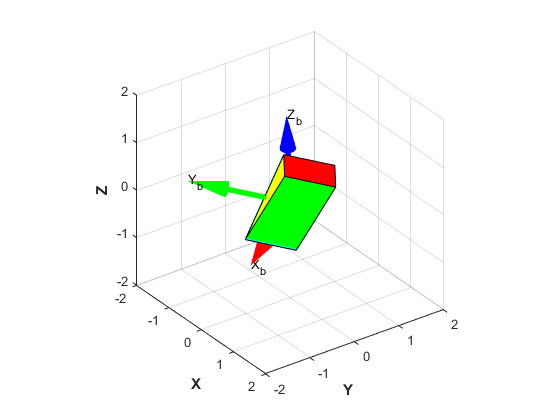

OBJ_pass_rot.animate();

Now try the **Eigenaxis** animation

 OBJ_ee = bh_eul_eigenaxis_CLS(ref_DCM_bRg)

OBJ_ee =   bh_eul_eigenaxis_CLS with properties:

            e_col: [3×1 double]
        theta_rad: 2.9424
    DCM_B_given_A: [3×3 double]
        theta_deg: 168.5871
           e_axis: [-0.4963 0.2554 0.8297]
      vis_DCM_bRg: [3×3 double]


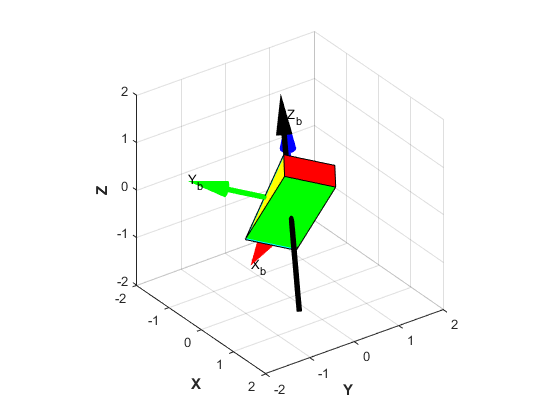


 OBJ_ee.animate();